format default

% Car parameters
wheel_radius = 101e-3

wheel_radius = 0.1010

small_gear = 18e-3

small_gear = 0.0180

big_gear = 113.4e-3

big_gear = 0.1134

axis_distance = 253e-3

axis_distance = 0.2530

tank_volume = 24e-3

tank_volume = 0.0240

tank_pressure = 9e5

tank_pressure = 900000

rolling_force = 15

rolling_force = 15

rotation_distance_moved = 113e-3

rotation_distance_moved = 0.1130


%Engine parameters
ambient_pressure = 103080

ambient_pressure = 103080

limit_pressure = 2e5

limit_pressure = 200000

inlet_start_time = 0.00

inlet_start_time = 0

connecting_rod_length = 90e-3

connecting_rod_length = 0.0900

piston_head_radius = 15e-3

piston_head_radius = 0.0150

tdc_volume = 132.3e-9*2 + 1e-4*piston_head_radius^2*pi

tdc_volume = 3.3529e-07

leverarm_length = 22e-3 %stroke_volume / (2*piston_head_radius^2*pi)

leverarm_length = 0.0220

stroke_volume = leverarm_length * 2 * piston_head_radius^2*pi

stroke_volume = 3.1102e-05

stroke_volume_fn = @(x) stroke_volume * (sin(x - pi/2) + 1) ./ 2 + tdc_volume;
max_stroke_volume = stroke_volume_fn(pi)

max_stroke_volume = 3.1437e-05


crankshaft_diameter = 10e-3 % m

crankshaft_diameter = 0.0100

crankshaft_length = 100e-3 % m

crankshaft_length = 0.1000


% Tröghet
material_density = 8050 % Stål 7750-8050 kg/m^3

material_density = 8050


standard_flywheel_diameter_inner = 10e-3 % m

standard_flywheel_diameter_inner = 0.0100

standard_flywheel_diameter_outer = 90e-3 % m

standard_flywheel_diameter_outer = 0.0900

standard_flywheel_width = 20e-3 % m

standard_flywheel_width = 0.0200


crankwheel_diameter_inner = 10e-3 % m

crankwheel_diameter_inner = 0.0100

crankwheel_diameter_outer_high = 60e-3 % m

crankwheel_diameter_outer_high = 0.0600

crankwheel_diameter_outer_low = 22e-3 % m

crankwheel_diameter_outer_low = 0.0220

crankwheel_width_high = 5e-3 % m

crankwheel_width_high = 0.0050

crankwheel_width_low = 10e-3 % m

crankwheel_width_low = 0.0100


flywheel_diameter_inner = crankshaft_diameter % m

flywheel_diameter_inner = 0.0100

flywheel_diameter_outer = 90e-3 % m

flywheel_diameter_outer = 0.0900

## Gearing calculations

init_system_gearing = 1/6

init_system_gearing = 0.1667

calculated_system_gearing = rotation_distance_moved/(wheel_radius*2*pi)

calculated_system_gearing = 0.1781

## Inlet Close Calculations

syms P_cyl P_tank x V_cyl V_tot V_inlet X X_stop V_tdc P_limiter V_stroke P_ambient
format long

V_inlet = V_stroke*(sin(X_stop*2*pi - pi/2) + 1) / 2 + V_tdc;
P_cyl = P_limiter .* V_inlet ./ (V_stroke*(sin(pi - pi/2) + 1) ./ 2 + V_tdc);
simplified_ekv = simplify(P_cyl)

$$simplified\_ekv = \frac{P_{\mathrm{limiter}}\,\left(V_{\mathrm{tdc}}+\frac{V_{\mathrm{stroke}}}{2}-\frac{V_{\mathrm{stroke}}\,\cos\left(2\,\pi \,X_{\mathrm{stop}}\right)}{2}\right)}{V_{\mathrm{tdc}}+V_{\mathrm{stroke}}}$$


ekv = solve(P_ambient == simplified_ekv, X_stop, "ReturnConditions", true);
ekv.X_stop(2)

$$ans = \frac{\mathrm{acos}\left(\frac{2\,V_{\mathrm{tdc}}+V_{\mathrm{stroke}}-\frac{2\,P_{\mathrm{ambient}}\,\left(V_{\mathrm{tdc}}+V_{\mathrm{stroke}}\right)}{P_{\mathrm{limiter}}}}{V_{\mathrm{stroke}}}\right)+2\,\pi \,k}{2\,\pi }$$

ekv.conditions

$$ans = \left(\begin{array}{c} k\in \mathbb{Z}\wedge P_{\mathrm{limiter}}\neq 0\wedge V_{\mathrm{stroke}}\neq 0\\ k\in \mathbb{Z}\wedge P_{\mathrm{limiter}}\neq 0\wedge V_{\mathrm{stroke}}\neq 0 \end{array}\right)$$


k = 0;
P_ambient = ambient_pressure;
V_tdc = tdc_volume;
V_stroke = stroke_volume;
P_limiter = limit_pressure;
inlet_stop_time = double(eval(ekv.X_stop(2)))

inlet_stop_time =    0.253239305301461



% X_plot = linspace(2*pi*X_stop, 2*pi, 10000)
% Ys = (P_tank.*(cos(2.*pi.*X_stop) - 1))./(cos(X_plot) - 1)
% Ys(length(X_plot) / 2)
% min(Ys((length(X_plot) / 2) - length(X_plot) / 4: (length(X_plot) / 2) + length(X_plot) / 4))
% plot(X_plot(1:length(X_plot) / 2),Ys(1:length(X_plot) / 2))
% grid on

## Single Working Pressure

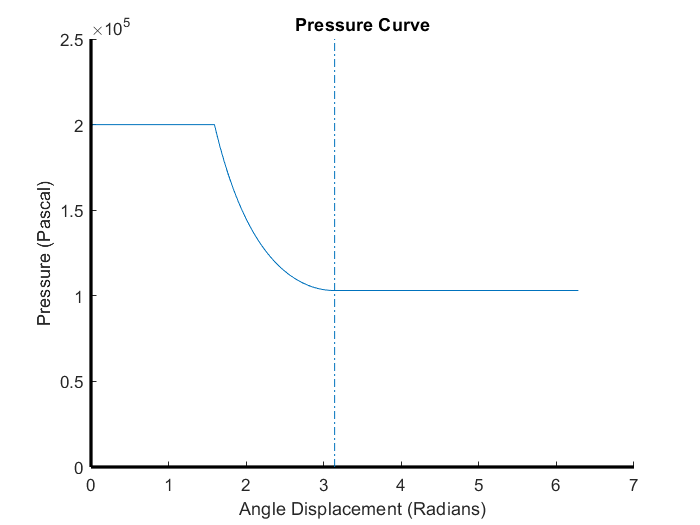

xs = linspace(0, 2*pi, 2000);
inlet_start_length = int32(length(xs)*inlet_start_time);
inlet_length = int32(length(xs)*inlet_stop_time);
xs_pi_length = length(xs) / 2;

pressure = [
    ones(1, inlet_start_length)*ambient_pressure ...
    ones(1, inlet_length - inlet_start_length) * limit_pressure ...
    limit_pressure*stroke_volume_fn(inlet_stop_time*2*pi)./stroke_volume_fn(xs(inlet_length + 1:xs_pi_length)) ...
    ones(1, xs_pi_length)*ambient_pressure
];

forces = (pressure - ambient_pressure) * piston_head_radius^2 * pi;

connecting_rod_effect = cos(asin(leverarm_length.*sin(xs)/connecting_rod_length));
leverarm_effect = abs((leverarm_length*cos(xs) + sqrt(connecting_rod_length^2 + leverarm_length^2*cos(xs).^2 - leverarm_length^2))*leverarm_length.*sin(xs)/connecting_rod_length);
torque = connecting_rod_effect.*leverarm_effect.*forces;

pplot(xs, pressure, 'Pressure Curve', 'Angle Displacement (Radians)','Pressure (Pascal)')

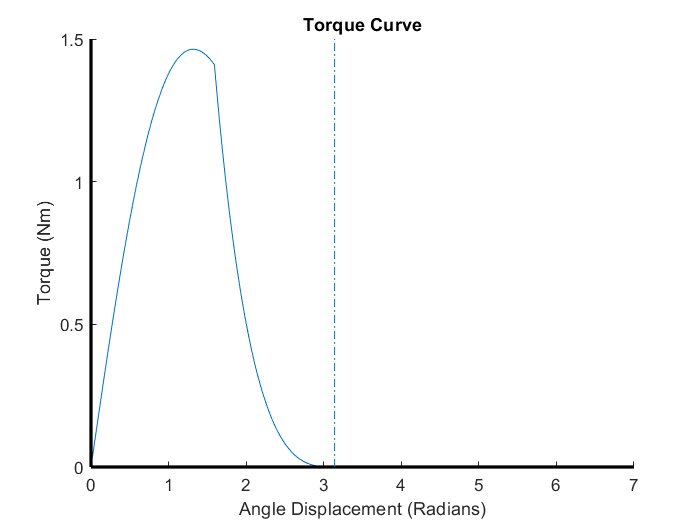

pplot(xs, torque, 'Torque Curve', 'Angle Displacement (Radians)','Torque (Nm)')

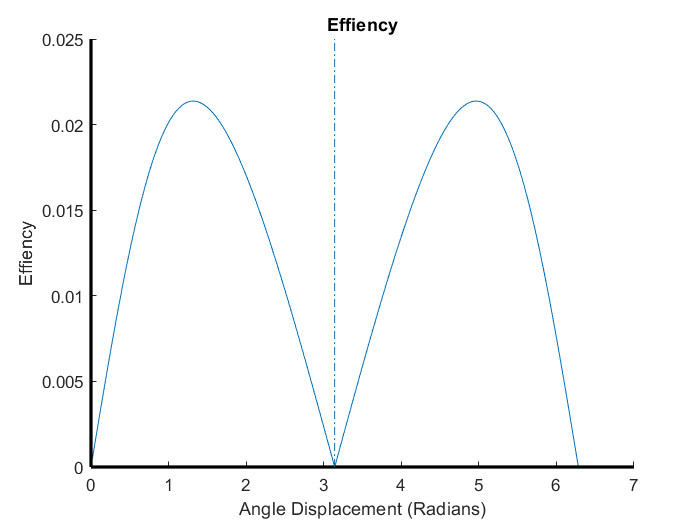

pplot(xs, connecting_rod_effect.*leverarm_effect, 'Effiency', 'Angle Displacement (Radians)','Effiency')


[max_torque,index] = max(torque)

max_torque =    1.464230107455317


index =    420


max_force = forces(index)

max_force =   68.508710996832619


angle_degrees =  xs(index) * 180 / pi

angle_degrees =   75.457728864432212


work = trap_int(xs, torque)

work =    2.162508755848250


## Tröghetsmoment

syms flywheel_width

moi_fn = @(w,d_i,d_o) - pi*material_density*w*(d_i^3 - d_o^3)/12;

flywheel_standard_moments_of_inertia = moi_fn(standard_flywheel_width, standard_flywheel_diameter_inner, standard_flywheel_diameter_outer);
max_moments_of_inertia = flywheel_standard_moments_of_inertia*3

max_moments_of_inertia =    0.092054947935488


crankshaft_moments_of_inertia = moi_fn(crankshaft_length, 0,crankshaft_diameter)

crankshaft_moments_of_inertia =      2.107485071783154e-04


crankwheel_moments_of_inertia = moi_fn(crankwheel_width_high, crankwheel_diameter_inner, crankwheel_diameter_outer_high) + moi_fn(crankwheel_width_low, crankwheel_diameter_inner, crankwheel_diameter_outer_low)

crankwheel_moments_of_inertia =    0.002468876611893


flywheel_moments_of_inertia = moments_of_inertia_calc_width(flywheel_diameter_inner, flywheel_diameter_outer, material_density);
flywheel_width = eval(solve(max_moments_of_inertia == crankshaft_moments_of_inertia + crankwheel_moments_of_inertia + flywheel_moments_of_inertia, flywheel_width))

flywheel_width =    0.058253461538462


## Solenoid calculations

rotation_speed = 160

rotation_speed =    160


pre_solenoid_starting_time = 7/960

pre_solenoid_starting_time =    0.007291666666667


solenoid_act_time = 21/960

solenoid_act_time =    0.021875000000000


tot_solenoid_act_time = pre_solenoid_starting_time + solenoid_act_time

tot_solenoid_act_time =    0.029166666666667


solenoid_act_length = 1e-2

solenoid_act_length =    0.010000000000000


solenoid_act_acceleration = 32/35

solenoid_act_acceleration =    0.914285714285714


solenoid_act_speed = solenoid_act_acceleration*solenoid_act_time

solenoid_act_speed =    0.020000000000000



inlet_open_time = inlet_stop_time/(rotation_speed/60)

inlet_open_time =    0.094964739488048


## Simulation

num_rotations = 0;

angles = linspace(0, 2*pi, 1000);
inlet_stop_times = zeros(1, num_rotations);
Ps_tank = zeros(1, num_rotations);
pressures = zeros(num_rotations, length(angles));
torques = zeros(num_rotations, length(angles));
tot_work = 0;
V_inlet = stroke_volume_fn(X_stop*2*pi);
P_tank = tank_pressure;
P_limiter = min(tank_pressure, limit_pressure);

inlet_start_length = int32(length(angles)*inlet_start_time);
half_angle_length = length(angles) / 2;


minimal_work_required = rolling_force*rotation_distance_moved

minimal_work_required =    1.695000000000000



rotations_at_required_work = 0;
rotations_at_required_work_changed = true;

tic
while P_tank > ambient_pressure
    num_rotations = num_rotations + 1;
    
    X_stop = double(eval(ekv.X_stop(2)));
    inlet_stop_times(num_rotations) = X_stop;
    P_limiter = min(P_tank, limit_pressure);
    
    inlet_length = int32(length(angles)*X_stop);
    pressures(num_rotations, :) = [
        ones(1, inlet_start_length).*ambient_pressure ...
        ones(1, inlet_length - inlet_start_length).*P_limiter ...
        P_limiter*stroke_volume_fn(X_stop*2*pi)./stroke_volume_fn(angles(inlet_length + 1:half_angle_length)) ...
        ones(1, half_angle_length)*ambient_pressure
    ];
    
    torques(num_rotations, :) = (pressures(num_rotations, :) - ambient_pressure) * piston_head_radius^2 * pi.*abs((leverarm_length*cos(angles) + sqrt(connecting_rod_length^2 + leverarm_length^2*cos(angles).^2 - leverarm_length^2))*leverarm_length.*sin(angles)/connecting_rod_length);
    
    work_rotation = trap_int(angles, torques(num_rotations, :));
    tot_work = tot_work + work_rotation;
    
    if work_rotation <= minimal_work_required && rotations_at_required_work_changed
        rotations_at_required_work = num_rotations;
        rotations_at_required_work_changed = false;
    end
    
    P_tank = (P_tank*tank_volume - ambient_pressure*max_stroke_volume) / tank_volume;
    % P_tank = P_tank*(tank_volume - V_stroke) / tank_volume;
    Ps_tank(num_rotations) = P_tank;
end
toc

Elapsed time is 42.228102 seconds.



num_rotations

num_rotations =         5903


rotations_at_required_work

rotations_at_required_work =         5390


range = wheel_radius*2*pi*calculated_system_gearing*rotations_at_required_work

range =      6.090700000000001e+02


max_range = wheel_radius*2*pi*calculated_system_gearing*num_rotations

max_range =      6.670390000000000e+02


tot_work

tot_work =      1.232115051190987e+04



(Ps_tank(end) - Ps_tank(1))/num_rotations

ans =     -1.349992696086257e+02


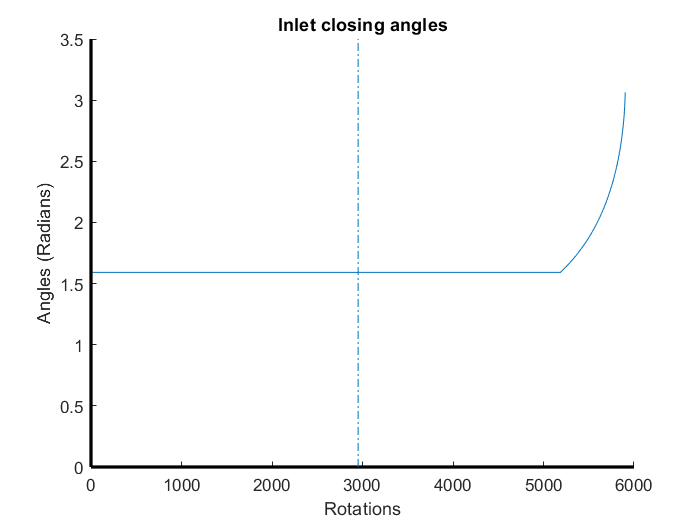


pplot(1:num_rotations, inlet_stop_times.*2.*pi, 'Inlet closing angles', 'Rotations', 'Angles (Radians)')

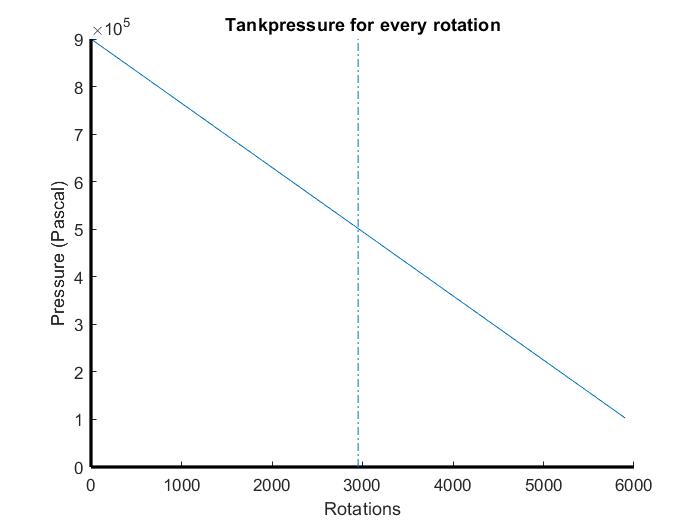

pplot(1:num_rotations, Ps_tank, 'Tankpressure for every rotation', 'Rotations','Pressure (Pascal)')

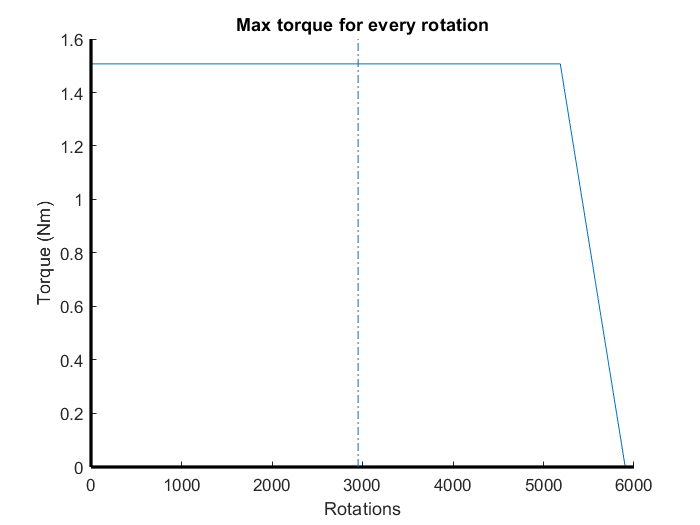

pplot(1:num_rotations, max(torques, [], 2), 'Max torque for every rotation', 'Rotations','Torque (Nm)')


% animate(angles, torques, 10)

%{
1000 =
     6079
     3.070626008368355e+04
     Elapsed time is 42.626548 seconds.
10000 = 
     6079
     3.070633930509749e+04
     Elapsed time is 318.851739 seconds.
%}


## Positioning test with light sensor

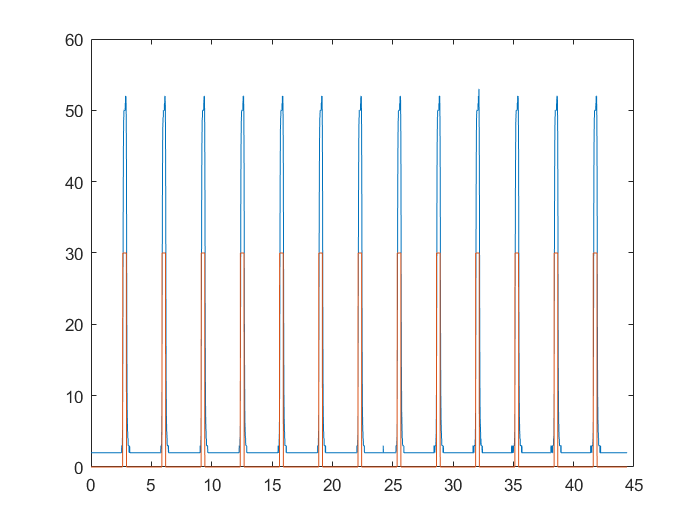

fid = fopen('data_points.json');
val = jsondecode(char(fread(fid,inf)'));
fclose(fid);


start_index = 1;
stop_index = 7000;
diff = 3;

X = (val(start_index:stop_index, 1) - val(1, 1)) ./ 1e6;
Y = val(start_index:stop_index,2);

highes = zeros(1, stop_index - start_index);
current_val = 0;
detected_high = false;
last_rise = 0;
rotation_speeds = [];

for i = start_index + 1:stop_index
    if Y(i) - Y(i-1) >= diff && ~detected_high
        current_val = 30;
        detected_high = true;
        rotation_speeds = [rotation_speeds; [X(i), 60/(X(i)-last_rise)]];
        last_rise = X(i);
    elseif Y(i-1) - Y(i) >= diff && detected_high
        current_val = 0;
        detected_high = false;
    end
    highes(i) = current_val;
end

plot(X, Y, X, highes)

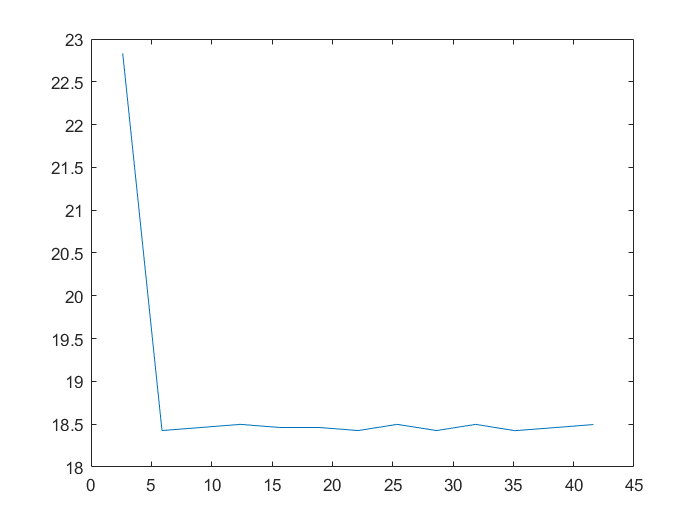

rotation_speeds;
plot(rotation_speeds(:,1), rotation_speeds(:,2))

## Pressure Sensor Data

fid = fopen('pressure_data_points_512_v3.json');
pressure_data_512 = jsondecode(char(fread(fid,inf)'));
fclose(fid);
fid = fopen('pressure_data_points_4096_v2.json');
pressure_data_4096 = jsondecode(char(fread(fid,inf)'));
fclose(fid);
fid = fopen('pressure_data_points_2048.json');
pressure_data_2048 = jsondecode(char(fread(fid,inf)'));
fclose(fid);

start_index = 1;
stop_index = 2000;

X_512 = (pressure_data_512(start_index:stop_index, 1) - pressure_data_512(1, 1)) ./ 1e6;
Y_512 = pressure_data_512(start_index:stop_index,2);
X_2048 = (pressure_data_2048(start_index:stop_index, 1) - pressure_data_2048(1, 1)) ./ 1e6;
Y_2048 = pressure_data_2048(start_index:stop_index,2);
X_4096 = (pressure_data_4096(start_index:stop_index, 1) - pressure_data_4096(1, 1)) ./ 1e6;
Y_4096 = pressure_data_4096(start_index:stop_index,2);

(X_512(end) - X_512(1))/(stop_index - start_index)

ans = 0.0099

(X_2048(end) - X_2048(1))/(stop_index - start_index)

ans = 0.0159

(X_4096(end) - X_4096(1))/(stop_index - start_index)

ans = 0.0239

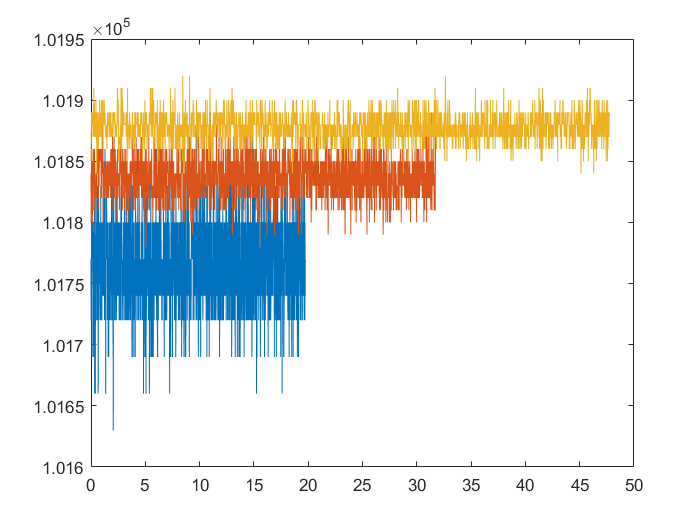


plot(X_512, Y_512, X_2048, Y_2048, X_4096, Y_4096)

## Positioning test with hall effect sensor

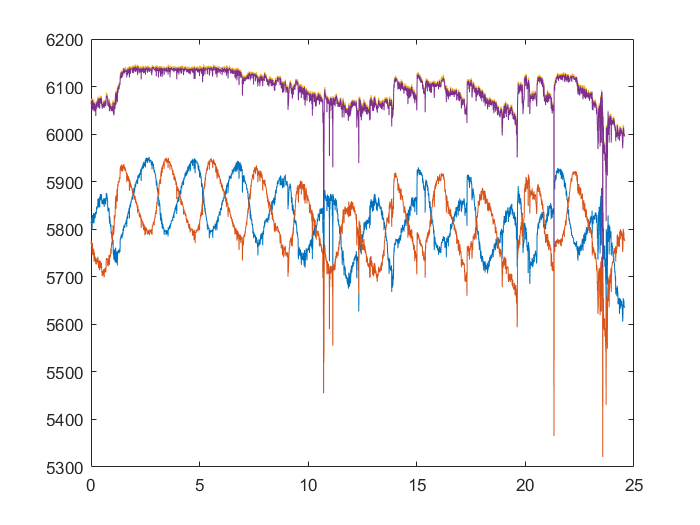

fid = fopen('data_points_v3.json');
str = char(fread(fid,inf)'); 
fclose(fid); 
val = jsondecode(str);

start_index = 1;
stop_index = 3000;
offset = 304;
W = 0.2;

X = (val(start_index:stop_index, 1) - val(1, 1)) ./ 1e6;
plot(X, val(start_index:stop_index,2), X, val(start_index:stop_index,3), X, val(start_index:stop_index,4), X, val(start_index:stop_index,5))

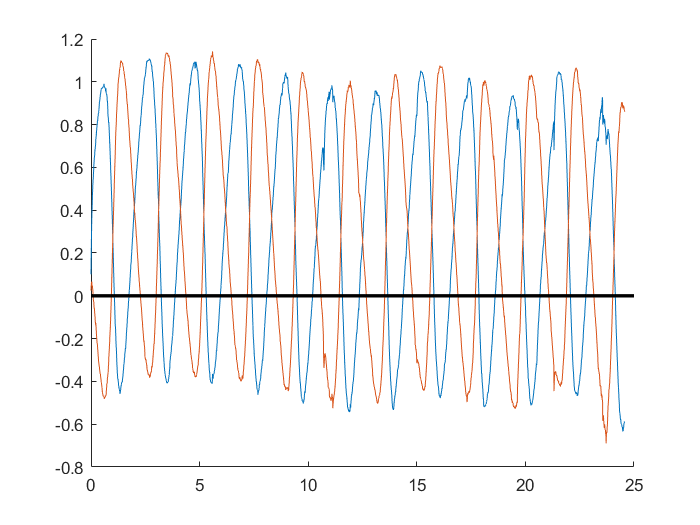

Y_comp = [
    ((val(start_index:stop_index,2) - val(start_index:stop_index,4) + offset) ./ 100)';
    ((val(start_index:stop_index,3) - val(start_index:stop_index,5) + offset) ./ 100)'
];

Y_smoothed = [Y_comp(1,:);Y_comp(2,:)];
Y_smoothed(1,1) = W*Y_smoothed(1,1);
Y_smoothed(2,1) = W*Y_smoothed(2,1);

for i = 2:stop_index
    Y_smoothed(1,i) = W*Y_smoothed(1,i) + (1-W)*Y_smoothed(1,i-1);
    Y_smoothed(2,i) = W*Y_smoothed(2,i) + (1-W)*Y_smoothed(2,i-1);
end

figure
hold on
plot(X, Y_smoothed(1,:), X, Y_smoothed(2,:))
%plot(X, Y_comp(1,:), X, Y_comp(2,:))
line(xlim, [0,0], 'LineWidth', 2, 'Color', 'k')
hold off

function pplot(xs,ys, tit, xlab, ylab)
    figure
    hold on
    plot(xs, ys)
    title(tit)
    xlabel(xlab)
    ylabel(ylab)
    line(xlim, [0,0], 'LineWidth', 2, 'Color', 'k')
    line([0 0], ylim, 'LineWidth', 2, 'Color', 'k')
    yl = ylim;
    middle_val = xs(int32(length(xs) / 2));
    line([middle_val middle_val], [0 yl(2)], 'LineStyle', '-.')
    hold off
end

function int = trap_int(x,y)
    h = x(2) - x(1);
    sum = y(1);
    len = (length(x) - mod(length(x), 2)) - 1;
    for n = 2:len
        sum = sum + (3 + (-1)^(n - 1))*y(n);
    end
    int = h/3*(sum + y(end));
end

function animate(x,y,step)
    figure
    set(gcf,'Visible','on')
    sizes = size(y);
    min_y = min(y, [], "all");
    max_y = max(y, [], "all");
    for i = 1:step:sizes(1)
        plot(x,y(i,:))
        axis([0 2*pi min_y max_y])
        pause(0.01)
    end
end

function moments_of_inertia = moments_of_inertia_calc(diameter_inner, diameter_outer, width, material_density)
    syms r
    moments_of_inertia = eval(int(material_density*width*r^2*2*pi(),r,diameter_inner/2,diameter_outer/2)); % kg*m^2
end
function moments_of_inertia = moments_of_inertia_calc_width(diameter_inner, diameter_outer, material_density);
    syms r flywheel_width
    moments_of_inertia = eval(int(material_density*flywheel_width*r^2*2*pi(),r,diameter_inner/2,diameter_outer/2));
end